# LIDAR Functions

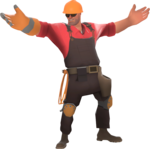

Eliyahu Suskind and Mahdi, 3/6/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace

### Set Up Lidar

disp("program running"); %indicate lidar code starts ok

program running


warning('off', 'all'); %temporarily turn matlab warnings off

serialObjs = instrfind; 
if ~isempty(serialObjs)
    fclose(serialObjs);
    delete(serialObjs);
end

clear
clc
comPort = "COM14";
disp("Com Port Set")

Com Port Set


### Connect to Lidar

disp("connecting to lidarand setting Lidar parameters");

connecting to lidarand setting Lidar parameters


disp("expect a short delay while setting...");

expect a short delay while setting...



lidar = serial(comPort, 'baudrate', 115200); %creatig a serial port for lidar
set(lidar, 'Timeout', 2);
set(lidar, 'InputBufferSize', 200000);
set(lidar, 'Terminator', 'LF/CR');

fopen(lidar);
pause(0.3);
fprintf(lidar, 'SCIP2.0');
pause(0.3);
fscanf(lidar);
fprintf(lidar, 'W');
pause(0.3);
fscanf(lidar);
fprintf(lidar,'BW');
pause(0.3);
fscanf(lidar);
fprintf(lidar, 'MD0044072500');
pause(0.3);
fscanf(lidar);
clc
disp("Lidar set")

Lidar set


### Inititalize Lidar display figure Window

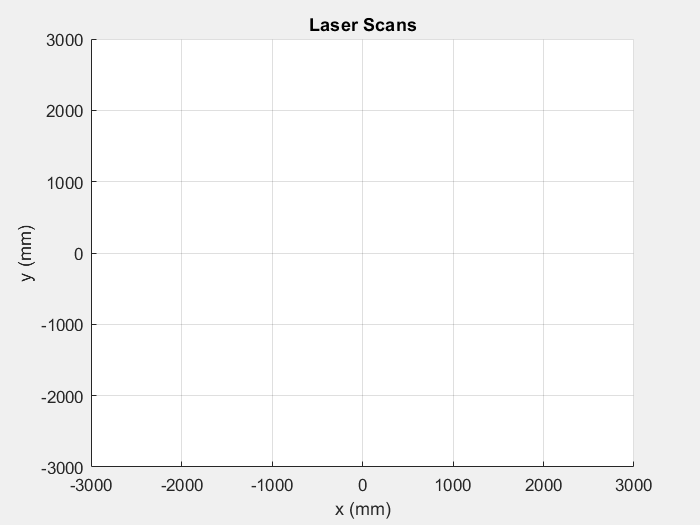

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle', 'off', ...
    'MenuBar', 'figure', 'units', 'normalized', 'Visible', 'on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'units', 'normalized', 'NextPlot', ...
    'replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String='Laser Scans';
LaserPlot1.axis1.XLabel.String='X Axis';
LaserPlot1.axis1.YLabel.String='Y Axis';

laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', ...
    'none', 'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-3000 3000 -3000 3000])
xlabel('x (mm)')
ylabel('y (mm)')

disp("Laser Scans figure set");

Laser Scans figure set


### Sample and Visualize Data

disp("Read and Plot Lidar Data, type and hold cntrl-c to stop")

Read and Plot Lidar Data, type and hold cntrl-c to stop


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


4


5


1


2


3


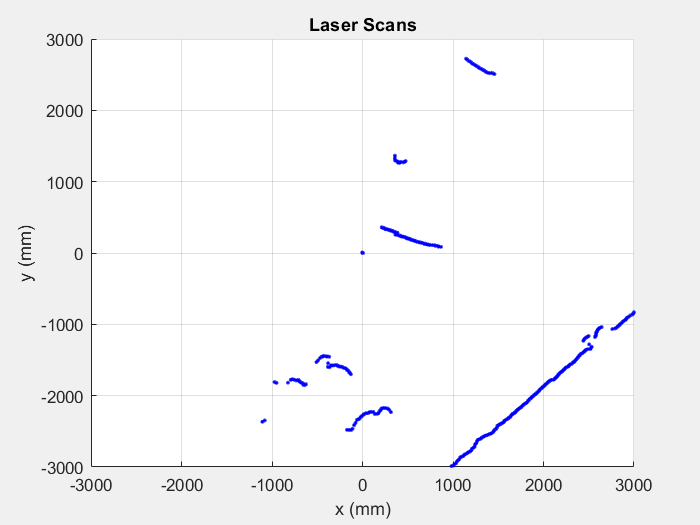

4


5



angles = (-120:240/682:120-240/682)*pi/180;
tStart = tic;
iscan = 1;
while (iscan == 1)
    disp("1")
    [A] = FunRoboLidarScan(lidar);
    disp("2")
    laserRange.XData = A .* cos(angles);
    disp("3")
    laserRange.YData = A .* sin(angles);
    disp("4")

    drawnow
    disp("5")
    pause(0.2)
    tElapsed = toc(tStart);
    if (tElapsed > 60)
        iscan = 0;
    end
end 


disp("Laser scan ended");

Laser scan ended


### Clean and Shutdown

End program by safely disconnecting from LIDAR

fprintf(lidar, 'QT');
fclose(lidar);
clear lidar;
warning('on');
disp("program ended");

program ended
